s=tf('s');

l = 0.092;
m_R = 0.412;
J_R = 8.9*10^-3;
B_R = 2.2*10^-3;
m_H = 0.220;
J_H = 0.694*10^-3;
B_H = 0.199*10^-6;
g = 9.82;

k_1 = -0.0005;
k_2 = -1;
k_3 = -0.1;

num = (-s/(J_R - m_H *l^2))

num =
 
     -s
  --------
  0.007038
 
Continuous-time transfer function.



denum = s^3 + ((-k_3+(B_R-B_H))/(J_R - m_H *l^2) + (B_H+k_1)/(J_H))*s^2 + ( (-k_2 - l*g*(m_R + m_H))/(J_R - m_H *l^2) + ((B_R-B_H)*(B_H+k_1))/((J_R - m_H *l^2)*J_H) )*s + (-l*g*(m_R+m_H)*(B_H+k_1))/((J_R - m_H *l^2)*J_H)

denum =
 
  s^3 + 13.8 s^2 + 60.73 s + 58.43
 
Continuous-time transfer function.



H3 = num / denum

H3 =
 
                        -s
  ----------------------------------------------
  0.007038 s^3 + 0.09713 s^2 + 0.4274 s + 0.4112
 
Continuous-time transfer function.



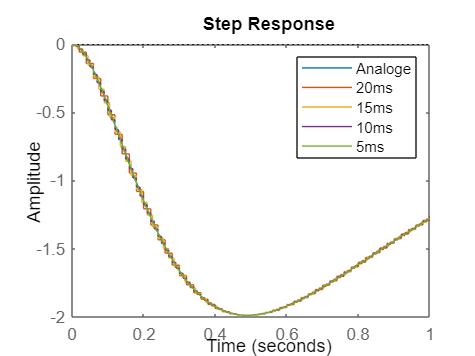


D1 = c2d(H3, 0.020,'tutsin');
D2 = c2d(H3, 0.015,'tutsin');
D3 = c2d(H3, 0.010,'tutsin');
D4 = c2d(H3, 0.005,'tutsin');


step(H3, D1, D2, D3, D4)
legend("Analoge", "20ms", "15ms", "10ms", "5ms")
xlim([0 1])